# Laborator 6

## Probleme

clear
clf
x = [1, 2, 2.5, 3, 4]

x =     1.0000    2.0000    2.5000    3.0000    4.0000


y = [-1, -1/3, 3/32, 4/3, 25]

y =    -1.0000   -0.3333    0.0938    1.3333   25.0000


[p, l] = LagrangeInterpolation(x, y); 
% l - cell array, acces prin l{i}
% p - functia de aproximare

### 1

for i = 1:length(x)
    fprintf("x = %f \t f(x) = %f \t p(x) = %f\n", x(i), y(i), p(x(i)))
end

x = 1.000000 	 f(x) = -1.000000 	 p(x) = -1.000000
x = 2.000000 	 f(x) = -0.333333 	 p(x) = -0.333333
x = 2.500000 	 f(x) = 0.093750 	 p(x) = 0.093750
x = 3.000000 	 f(x) = 1.333333 	 p(x) = 1.333333
x = 4.000000 	 f(x) = 25.000000 	 p(x) = 25.000000


### 2 + 3

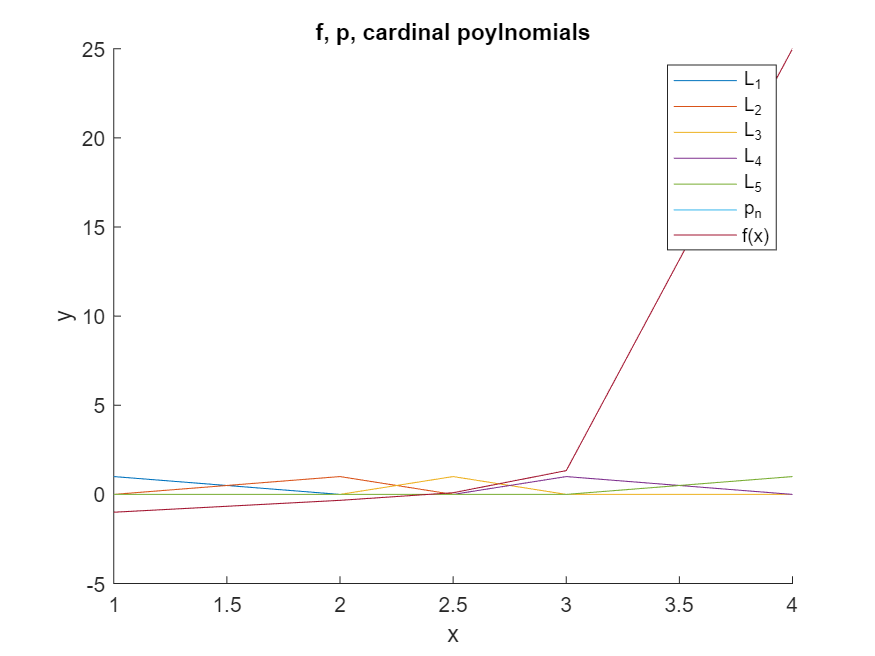

clf
y_l = cell(1,length(x) + 2);
figure;
hold on;
xlabel('x');
ylabel('y');
title('f, p, cardinal poylnomials');
legendArray = cell(1, length(x)); % Initialize legend cell array
for i = 1:length(x)
    y_l{i} = l{i}(x);
    plot(x, y_l{i});
    legendArray{i} = ['L_', num2str(i)]; % Concatenate 'y_' with current i value
    %hold on;
end

plot(x, p(x))
legendArray{length(x) + 1} = 'p_n'; % Concatenate 'y_' with current i value

plot(x, y)
legendArray{length(x) + 2} = 'f(x)';

legend(legendArray);

## 4

f = @(x_input) exp(x_input)

f = function_handle with value:
    @(x_input)exp(x_input)


x = (1:10)

x =      1     2     3     4     5     6     7     8     9    10


y = f(x)

y = 	1.0e+04 *

    0.0003    0.0007    0.0020    0.0055    0.0148    0.0403    0.1097    0.2981    0.8103    2.2026


[p, l] = LagrangeInterpolation(x, y);
xx = x + 0.5;
yy = f(xx);
for i = 1:length(x)
    fprintf("x = %f \t f(x) = %f \t p(x) = %f\n", xx(i), yy(i), p(xx(i)))
end

x = 1.500000 	 f(x) = 4.481689 	 p(x) = 6.770347
x = 2.500000 	 f(x) = 12.182494 	 p(x) = 11.749991
x = 3.500000 	 f(x) = 33.115452 	 p(x) = 33.270531
x = 4.500000 	 f(x) = 90.017131 	 p(x) = 89.926854
x = 5.500000 	 f(x) = 244.691932 	 p(x) = 244.772241
x = 6.500000 	 f(x) = 665.141633 	 p(x) = 665.034227
x = 7.500000 	 f(x) = 1808.042414 	 p(x) = 1808.262279
x = 8.500000 	 f(x) = 4914.768840 	 p(x) = 4914.035750
x = 9.500000 	 f(x) = 13359.726830 	 p(x) = 13364.387804
x = 10.500000 	 f(x) = 36315.502674 	 p(x) = 36215.059264


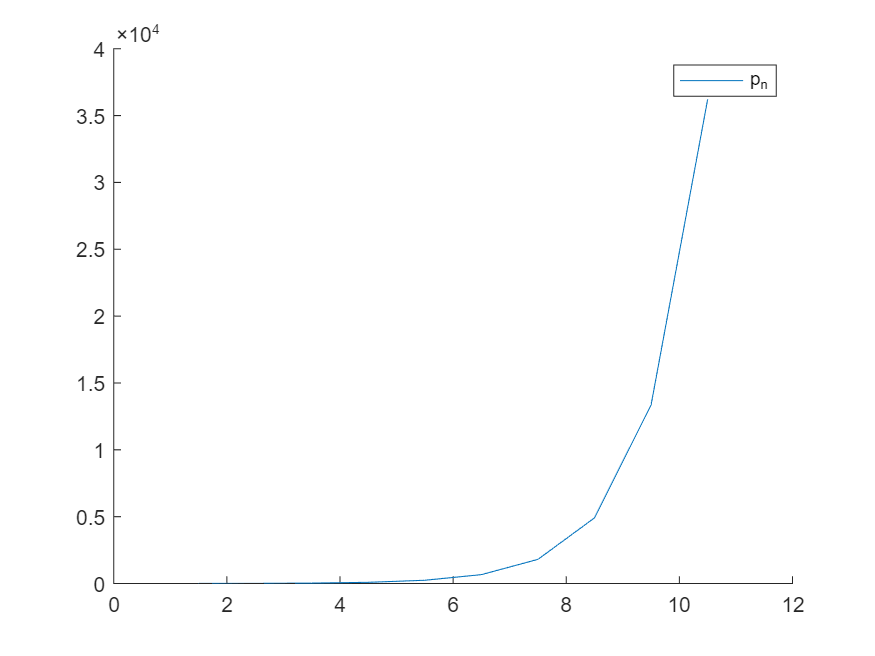

clf;
figure;
hold on;
plot(xx, p(xx));
legend('p_n');

### 5

%xx = x;
xx = 1:0.5:10

xx =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


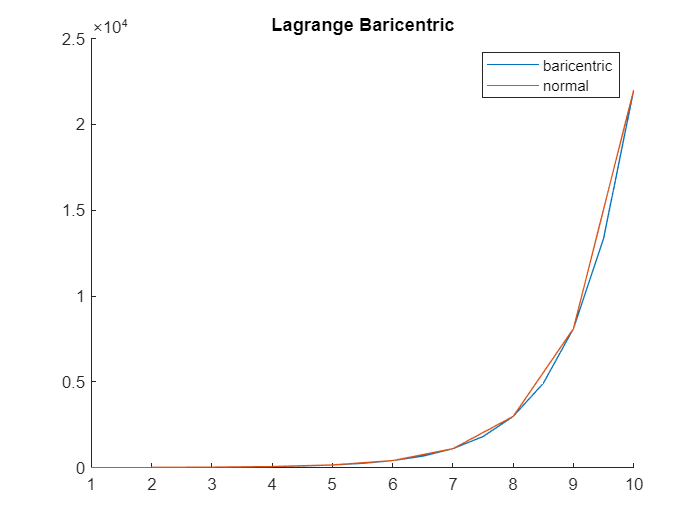

ff = baryLagrange(x, y, xx);
clf;
figure;
hold on;
title('Lagrange Baricentric');
plot(xx, ff)
plot(x, y)
legend('baricentric', 'normal')

## Probleme Practice

### 1

x = 1900:10:2010;
y = [75.995, 91.972, 105.711, 123.203, 131.669, 150.697, 179.323, 203.212, 226.505, 249.633, 281.422, 308.786];
[p, l] = LagrangeInterpolation(x, y);
xx = [1975, 2018];
for i = 1:length(xx)
    fprintf('anul %d \t populatie estimata %f\n', xx(i), p(xx(i)))
end

anul 1975 	 populatie estimata 214.364389
anul 2018 	 populatie estimata -664.306813


### 2


$$f(x) = e^{x^2 - 1}
$$


f = @(x) exp(x .^ 2 - 1);
x = [1, 1.1, 1.2, 1.3, 1.4];
y = f(x);
[p, l] = LagrangeInterpolation(x, y);

xx = 1.25;
yy = p(xx);
err = abs(yy - f(xx));
fprintf("x = %f \t f(x)1 = %.8f \t p(x) = %.8f \t error = %.15f\n", xx, f(xx), yy, err);

x = 1.250000 	 f(x)1 = 1.75505466 	 p(x) = 1.75495733 	 error = 0.000097328098152


Avem nr echidistante intre [1, 1.4] => aplicam formula de limitare a erorii cand avem f continua si noduri echidistante


$$\left|f(x) - p(x)\right| \le \frac{1}{4(n+1)}Mh^{n+1} \\
\left|f^{(n+1)}(x)\right| \le M$$


n = length(x) - 1;
b = 1.4;
a = 1;
h = (b - a) / n

h = 0.1000

% pt a gasi nth + 1 derivative
syms x_sym
f_symbolic = exp(x_sym ^ 2 - 1);
df_symbolic = diff(f_symbolic, x_sym, n + 1);
df = matlabFunction(df_symbolic)

df = function_handle with value:
    @(x_sym)x_sym.*exp(x_sym.^2-1.0).*1.2e+2+x_sym.^3.*exp(x_sym.^2-1.0).*1.6e+2+x_sym.^5.*exp(x_sym.^2-1.0).*3.2e+1


% cautam valoarea max a functiei derivata de n+1 ori pt x in [1, 1.4], pt a stabili M
x_values = linspace(1, 1.4, 1000);
y_values = df(x_values);
max_derivative = max(abs(y_values));
fprintf("max_derivative = %.15f\n", max_derivative);

max_derivative = 2034.886801345909134


M = 2035;
delimitare = M * h^(n + 1) / (4 * (n + 1))

delimitare = 0.0010

**Concluzie**: $\left|e^{x^2 - 1}  - p(x)\right| \le 10^{-3}$

Erorarea depinde de faptul ca nodurile trebuie sa fie echidistante intr-un interval [a, b], si depinde de nodurile in sine alese

### 3

$\sqrt{115}$  cu 3 zecimale exacte, prin interpolarea Lagrange

f = @(x) x .^ (1/2);
a = 100;
b = 400;
n = 6;
h = (b - a) / n;
x = a:h:b

x =    100   150   200   250   300   350   400


y = f(x);
int_x = [115];
int_y = f(int_x);
[p, l] = LagrangeInterpolation(x, y);
fprintf("x = %d \t f(x) = %.15f \t p(x) = %.15f\n \t err = %.15f", int_x(1), int_y, p(int_x), abs(p(int_x) - int_y))

x = 115 	 f(x) = 10.723805294763608 	 p(x) = 10.722921681782257
 	 err = 0.000883612981351

### 4

a) Runge $f: \left[-5, 5\right] \rightarrow \mathbb{R}, f(x) = \left(1+x^2\right)^{-1}$

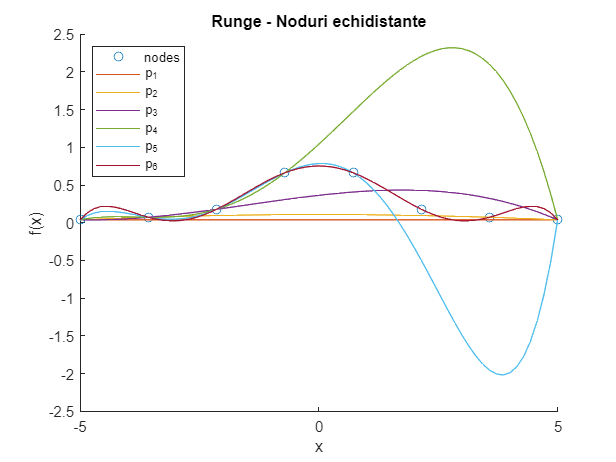

f = @(x) (1 + x .^ 2) .^ (-1);
a = -5;
b = 5;
n = 7;
h = (b - a) / n;
x = a:h:b;
y = f(x);
% form inputs
x_inputs = cell(1, n);
x_inputs{1} = [x(1), x(end)];
for i = 2:n
    x_inputs{i} = [x_inputs{i - 1}, x(i)];
end

figure;
hold on;
title('Runge - Noduri echidistante');
xlabel('x');
ylabel('f(x)');
% interpolation points
int_x = a:h*.10:b;
plot(x, y, 'o');
legendArray = cell(1, length(x_inputs));
legendArray{1} = 'nodes';
for i = 1:length(x_inputs) - 1
    %x_inputs{i};
    y = f(x_inputs{i});
    [p_i, l] = LagrangeInterpolation(x_inputs{i}, y);
    
    plot(int_x, p_i(int_x));
    legendArray{i + 1} = ['p_{', num2str(i), '}'];
end
legend(legendArray, 'Location', 'northwest');

Chebyshev second kind


$$x_k = cos\left(\frac{2k - 1}{2n}\pi\right), \ k = \overline{1,n}$$


f = @(x) (1 + x .^ 2) .^ (-1);
a = -5;
b = 5;
n = 7;
x = cos((2 * (1:n) - 1) / (2 * n) * pi)

x =     0.9749    0.7818    0.4339    0.0000   -0.4339   -0.7818   -0.9749


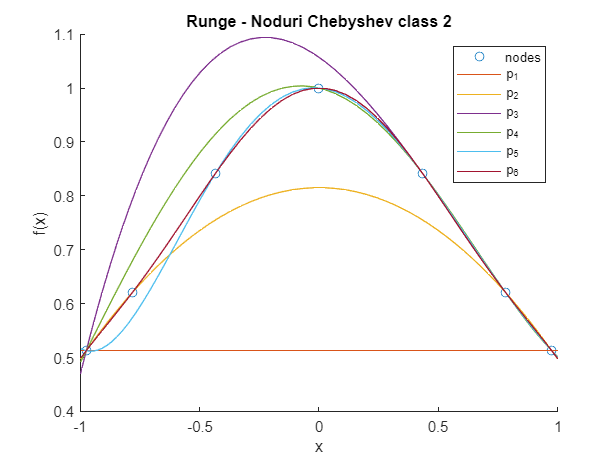

y = f(x);
% form inputs
x_inputs = cell(1, n);
x_inputs{1} = [x(1), x(end)];
for i = 2:n
    x_inputs{i} = [x_inputs{i - 1}, x(i)];
end

figure;
hold on;
title('Runge - Noduri Chebyshev class 2');
xlabel('x');
ylabel('f(x)');
% interpolation points
int_n = n * 10;
int_x = cos((2 * (1:int_n) - 1) / (2 * int_n) * pi);
plot(x, y, 'o');
legendArray = cell(1, length(x_inputs));
legendArray{1} = 'nodes';
for i = 1:length(x_inputs) - 1
    %x_inputs{i};
    y = f(x_inputs{i});
    [p_i, l] = LagrangeInterpolation(x_inputs{i}, y);
    
    plot(int_x, p_i(int_x));
    legendArray{i + 1} = ['p_{', num2str(i), '}'];
end
legend(legendArray, 'Location', 'northeast');

b) Bernstein $f : \left[-1, 1\right] \rightarrow \mathbb{R}, \ f(x) = \left|x\right|$

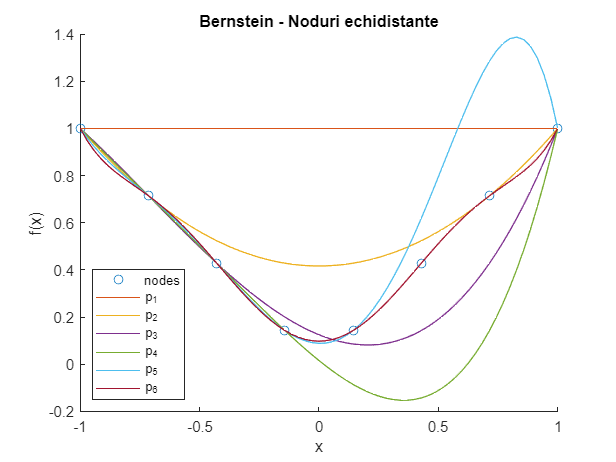

f = @(x) abs(x);
a = -1;
b = 1;
n = 7;
h = (b - a) / n;
x = a:h:b;
y = f(x);
% form inputs
x_inputs = cell(1, n);
x_inputs{1} = [x(1), x(end)];
for i = 2:n
    x_inputs{i} = [x_inputs{i - 1}, x(i)];
end

figure;
hold on;
title('Bernstein - Noduri echidistante');
xlabel('x');
ylabel('f(x)');
% interpolation points
int_x = a:h*.10:b;
plot(x, y, 'o');
legendArray = cell(1, length(x_inputs));
legendArray{1} = 'nodes';
for i = 1:length(x_inputs) - 1
    %x_inputs{i};
    y = f(x_inputs{i});
    [p_i, l] = LagrangeInterpolation(x_inputs{i}, y);
    
    plot(int_x, p_i(int_x));
    legendArray{i + 1} = ['p_{', num2str(i), '}'];
end
legend(legendArray, 'Location', 'southwest');

Chebyshev second kind


$$x_k = cos\left(\frac{2k - 1}{2n}\pi\right), \ k = \overline{1,n}$$


f = @(x) abs(x);
a = -1;
b = 1;
n = 7;
x = cos((2 * (1:n) - 1) / (2 * n) * pi)

x =     0.9749    0.7818    0.4339    0.0000   -0.4339   -0.7818   -0.9749


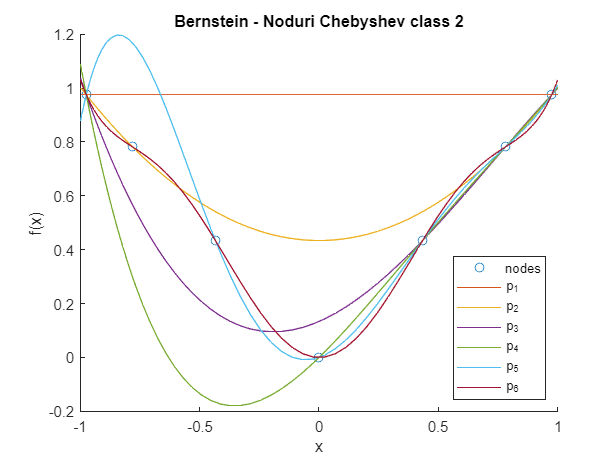

y = f(x);
% form inputs
x_inputs = cell(1, n);
x_inputs{1} = [x(1), x(end)];
for i = 2:n
    x_inputs{i} = [x_inputs{i - 1}, x(i)];
end

figure;
hold on;
title('Bernstein - Noduri Chebyshev class 2');
xlabel('x');
ylabel('f(x)');
% interpolation points
int_n = n * 10;
int_x = cos((2 * (1:int_n) - 1) / (2 * int_n) * pi);
plot(x, y, 'o');
legendArray = cell(1, length(x_inputs));
legendArray{1} = 'nodes';
for i = 1:length(x_inputs) - 1
    %x_inputs{i};
    y = f(x_inputs{i});
    [p_i, l] = LagrangeInterpolation(x_inputs{i}, y);
    
    plot(int_x, p_i(int_x));
    legendArray{i + 1} = ['p_{', num2str(i), '}'];
end
legend(legendArray, 'Location', 'southeast');